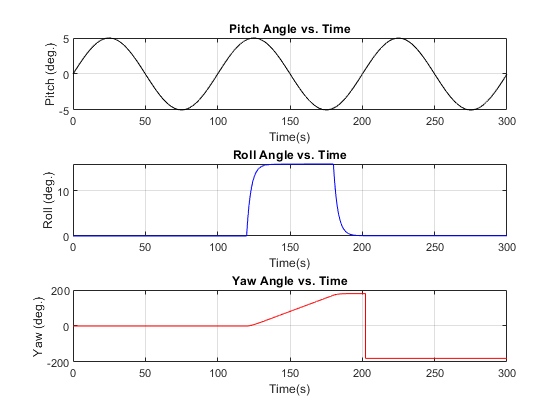

% The holy trinity:
clc; clear all; close all;

addpath('./ArtificialHorizon 1.3.0.2/')
load 'DFDR_data.mat';

% Initializing the beginning state of the DCM based on the initial pitch,
% roll, and yaw.
cbi_i_1 = [1 0 0; 0 cos(roll_i) sin(roll_i); 0 -sin(roll_i) cos(roll_i)];
cbi_i_2 = [cos(pitch_i) 0 -sin(pitch_i); 0 1 0; sin(pitch_i) 0 cos(pitch_i)];
cbi_i_3 = [cos(yaw_i) sin(yaw_i) 0; -sin(yaw_i) cos(yaw_i) 0; 0 0 1];

% Actually calculating the initial DCM
cbi_i = cbi_i_1*cbi_i_2*cbi_i_3;

% Setting up the incrementing cbi, as well as pre-allocating space for the
% attitude history while putting in the initial state at the first index.
cbi_current = cbi_i;
attitude_history = zeros(3,length(IMU_w));
attitude_history(:,1) = [pitch_i; roll_i; yaw_i];

% Setting up the velocity and position history in NED frame, pre-allocating space
velocity_history = zeros(3,length(IMU_f));
velocity_history(:,1) = [v_N_i; v_E_i; v_D_i];
position_history = zeros(3,length(IMU_f));
position_history(:,1) = [p_N_i; p_E_i; p_D_i];

% Setting up the angle-of-attack history, pre-allocating space and
% calculating initial state.
aoa_history = zeros(1,size(velocity_history,2));
aoa_history(1) = get_angle_of_attack(velocity_history(:,1),cbi_i);

% Calculating the first step manually, using the regular Euler method for
% the velocity. This makes the loop in the next part work properly with
% indexing using the modified Euler function.
cbi_current = iterate_cbi(cbi_current,IMU_w(:,2));
attitude_history(:,2) = get_attitude(cbi_current);
velocity_history(:,2) = increment_velocity(velocity_history(:,1), cbi_current, IMU_f(:,1));
position_history(:,2) = increment_position(position_history(:,1), velocity_history(:,1));
aoa_history(:,2) = get_angle_of_attack(velocity_history(:,2),cbi_current);
cbi_past = cbi_current;

% Main loop to calculate each of the required values for each time step,
% starting with the DCM.
for cbi_inc = 3:length(IMU_w)
    cbi_current = iterate_cbi(cbi_current,IMU_w(:,cbi_inc-1));
    attitude_history(:,cbi_inc) = get_attitude(cbi_current);
    % The commented line is from the original version. It's safe to ignore
    % it, I just left it in for debugging purposes and as a fallback.
    % velocity_history(:,cbi_inc) = increment_velocity(velocity_history(:,cbi_inc-1), cbi_current, IMU_f(:,cbi_inc-1)); 
    velocity_history(:,cbi_inc) = mod_increment_velocity(velocity_history(:,cbi_inc-1), cbi_current, cbi_past, IMU_f(:,cbi_inc-1), IMU_f(:,cbi_inc-2));
    position_history(:,cbi_inc) = increment_position(position_history(:,cbi_inc-1), velocity_history(:,cbi_inc-1));
    aoa_history(:,cbi_inc) = get_angle_of_attack(velocity_history(:,cbi_inc),cbi_current);
    cbi_past = cbi_current;
end

% Creating cell arrays for the sub-plot titles and y-labels.
attitude_titles = {'Pitch Angle vs. Time', 'Roll Angle vs. Time', 'Yaw Angle vs. Time'};
velocity_titles = {'Northern Velocity vs. Time', 'Easterly Velocity vs. Time', 'Downward Velocity vs. Time'};
position_titles = {'Northern Position vs. Time', 'Easterly Position vs. Time', 'Downward Position vs. Time'};

attitude_y_labels = {'Pitch (deg.)', 'Roll (deg.)', 'Yaw (deg.)'};
velocity_y_labels = {'North Velocity (ft/s)', 'East Velocity (ft/s)', 'Down Velocity (ft/s)'};
position_y_labels = {'North Position (ft.)', 'East Position (ft.)', 'Down Position (ft.)'};

% Generating all of the plots from the previously calculated values.
attitude_plot = generate_plot(DFDR_time, rad2deg(attitude_history) ,attitude_y_labels, attitude_titles);

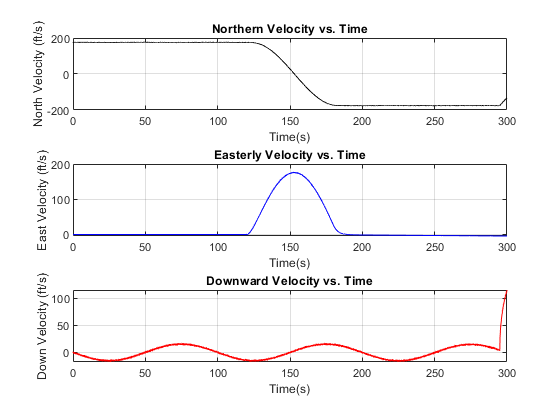

velocity_plot = generate_plot(DFDR_time, velocity_history, velocity_y_labels, velocity_titles);

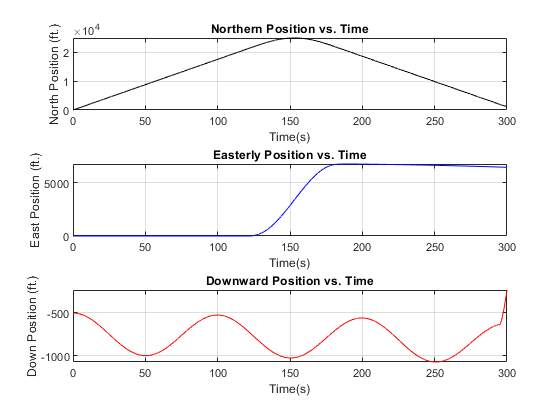

position_plot = generate_plot(DFDR_time, position_history, position_y_labels, position_titles);

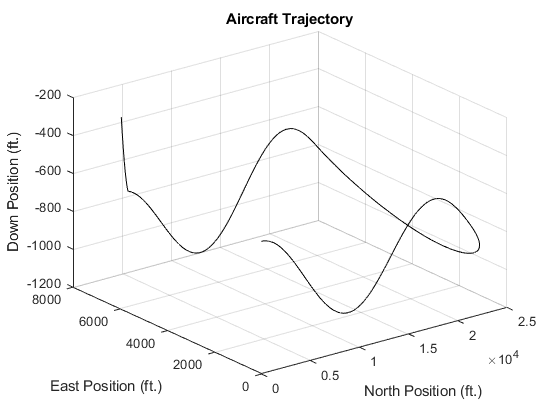

position_trajectory = generate_plot_3(position_history, position_y_labels, 'Aircraft Trajectory');

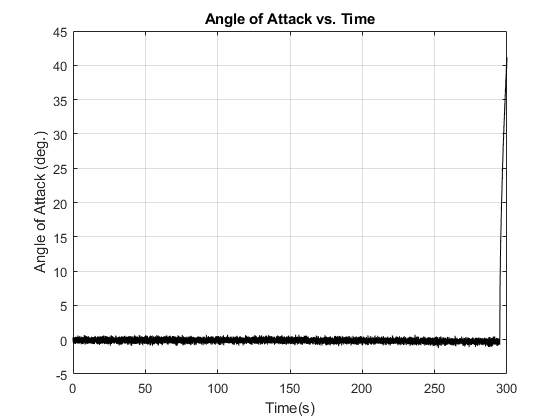

aoa_plot = generate_plot(DFDR_time, aoa_history, {'Angle of Attack (deg.)'}, {'Angle of Attack vs. Time'});

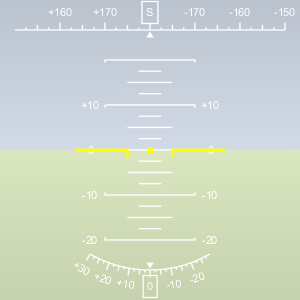


% Animating the data using every 100th data point from the history. Comment
% these 6 lines out if you just want the plots --and want it to finish
% running quickly!
figure(gcf().Number + 1);
AH = ArtificialHorizon;
step_size = 100;
for animation_inc = 1:step_size:size(attitude_history,2)
    AH.update(attitude_history(3,animation_inc),attitude_history(1,animation_inc),attitude_history(2,animation_inc))
end

function cbi_new = iterate_cbi(cbi_current, ang_vel)
    % Using the Euler method, this function calculates the next DCM from
    % a passed-in DCM and an angular velocity vector based on the algorithm
    % DCM_next = DCM_current - step_size*ang_vel_cross*DCM_current.
    h  = 0.01;
    cbi_new = cbi_current - h*get_cross_mat(ang_vel)*cbi_current;
end

function cross_mat = get_cross_mat(input_vector)
    % This function generates a cross-product matrix from a passed-in column
    % vector.
    cross_mat = [0, -input_vector(3), input_vector(2);...
                input_vector(3), 0, -input_vector(1);...
                -input_vector(2), input_vector(1), 0];
end

function attitude_vec = get_attitude(cbi_mat)
    % This function extracts the attitude angles from a passed-in DCM of the
    % 1-2-3 rotation sequence, and returns them in a column vector of
    % [pitch;roll;yaw].
    pitch_val = -asin(cbi_mat(1,3));
    roll_val = atan2(cbi_mat(2,3),cbi_mat(3,3));
    yaw_val = atan2(cbi_mat(1,2),cbi_mat(1,1));
    attitude_vec = [pitch_val; roll_val; yaw_val;];
end

function new_velocity_vec = increment_velocity(current_velocity, cbi_current, specific_force)
    % This function takes in the current velocity, current DCM, current
    % specific force, and uses gravity defined as down in the NED frame to
    % increment the ODE using Euler's method, with a constant time step
    % h=0.01s. The both velocities are resolved in the inertial frame i.
    h = 0.01;
    gi = [0;0;32.2];
    new_velocity_vec = current_velocity + h*(cbi_current'*specific_force + gi);
end

function new_velocity_vec = mod_increment_velocity(current_velocity, cbi_current, ...
    cbi_past, specific_force_current, specific_force_past)
    % This function takes in the current velocity, current DCM, previous DCM
    % current specific force, previous specific force, and uses gravity defined 
    % in the NED frame to increment the ODE using a modified Euler's method with 
    % a constant time step h=0.01s in order to get a more accurate result than the
    % standard Euler method. Both velocities are resolved in the inertial frame i.
    h = 0.01;
    gi = [0;0;32.2];
    new_velocity_vec = current_velocity + (h/2)*((cbi_current'*specific_force_current + gi) + (cbi_past'*specific_force_past + gi));
end

function new_positon_vec = increment_position(current_position, current_velocity)
    % This function takes in the current position vector and velocity
    % vector, then uses Euler's method to estimate the next position value
    % for a constant time step h=0.01s in the inertial frame.
    h = 0.01;
    new_positon_vec = current_position + h*current_velocity;
end

function aoa = get_angle_of_attack(velocity_vector, cbi)
    % This function takes in a velocity vector resolved in the inertial frame
    % i and the DCM to translate from frame i to the body-fixed frame b, then 
    % calculates the velocity in the body-fixed frame. Using this velocity,
    % the function then calculates the angle of attack.
    velocity_frame_b = cbi*velocity_vector;
    aoa = atan2d(velocity_frame_b(3),velocity_frame_b(1));
end

function plot_handle = generate_plot(x_vals, y_vals, y_labels, ttles)
    % Takes in a row of x values, a matrix of y values, and optional y-labels
    % and optional titles. The y_vals matrix is defined such that each row of the 
    % matrix is an independent data set, with the columns associated with 
    % the the x_vals data set. The if-statement and for-loop enables this script 
    % to plot up to 7 independent data sets simultaneously as vertically stacked 
    % subplots, assigning each a unique and pre-defined color following the sequence 
    % defined at the top of the script. If only a single data set is passed in, a 
    % standard plot, rather than subplots, is generated with the data.
    % 
    % The y_label parameter is an option to set the y-label(s) for the plot(s).
    % The y_labels should be passed as a cell array of strings, with the
    % length of the array matching the number of data sets being plotted.
    % 
    % The ttles parameter is an option to set the title(s) for the plot(s).
    % The titles should be passed as a cell array of strings, with the
    % length of the array matching the number of data sets being plotted.

    %Defining the sequence of colors
    color_sequence = ['k','b','r','g','c','m','y'];

    % Ensuring a new figure is used each time
    figure(gcf().Number + 1);

    % This first case handles the situation of a single input data-set, and
    % generates a plot.
    if size(y_vals,1) == 1
        plot_handle = plot(x_vals, y_vals(1,:),"Color",color_sequence(1));
        grid on;
        xlabel('Time(s)');
        if exist('y_labels', 'var') == 1
            ylabel(y_labels(1));
        end
        if exist('ttles', 'var') == 1
            title(ttles(1));
        end
        axis auto;
    else
        plot_handle = subplot(size(y_vals,1),1,1);
        % This handles the case of multiple input data sets, vertically
        % stacking the subplots.
        for plt_inc = 1:size(y_vals,1)
            subplot(size(y_vals,1),1,plt_inc)
            plot(x_vals, y_vals(plt_inc,:),"Color",color_sequence(plt_inc));
            grid on;
            xlabel('Time(s)');
            if exist('y_labels', 'var') == 1
                ylabel(y_labels(plt_inc));
            end
            if exist('ttles', 'var') == 1
                title(ttles(plt_inc));
            end
            axis auto;
        end
    end
end

function plot_handle = generate_plot_3(coordinate_vectors, axis_labels, ttle)
    % Takes in a 3xn matrix of values, plotting them in 3D space using the
    % built-in plot3() command. Rows are interpreted as [x;y;z] for the
    % input. Finally, some additional modifications are made to the plot to
    % improve their appearance.
    % 
    % The axis_labels parameter is an option to set the axis labels for the
    % plot, passed in as a cell array of 3 strings.
    % 
    % The ttle parameter is an option to set the title for the plot.

    figure(gcf().Number + 1);
    plot_handle = plot3(coordinate_vectors(1,:),coordinate_vectors(2,:),coordinate_vectors(3,:), 'Color', 'k');
    grid on;

    if exist('axis_labels', 'var') == 1
        xlabel(axis_labels(1));
        ylabel(axis_labels(2));
        zlabel(axis_labels(3));
    end
    if exist('ttle', 'var') == 1
        title(ttle);
    end
end

